# Particle trajectory visualisation

clc 
close all

## parameters

g    = 9.81;         % gravitational acceleration [m/s2]
zu   = 0.037;        % upper limit of the interface (entrance) [m]
zl   = 0.05;         % bottom limit of the interface (exit) [m]
rho1 = 976;          % density top layer [kg/m3]
rho2 = 1025;         % density bottom layer [kg/m3]
nu1  = 1.43e-6;      % viscosity top layer [m2/s]
nu2  = 1.012e-6;     % viscosity bottom layer [m2/s]
lam=0.35;

## Load the experimental data

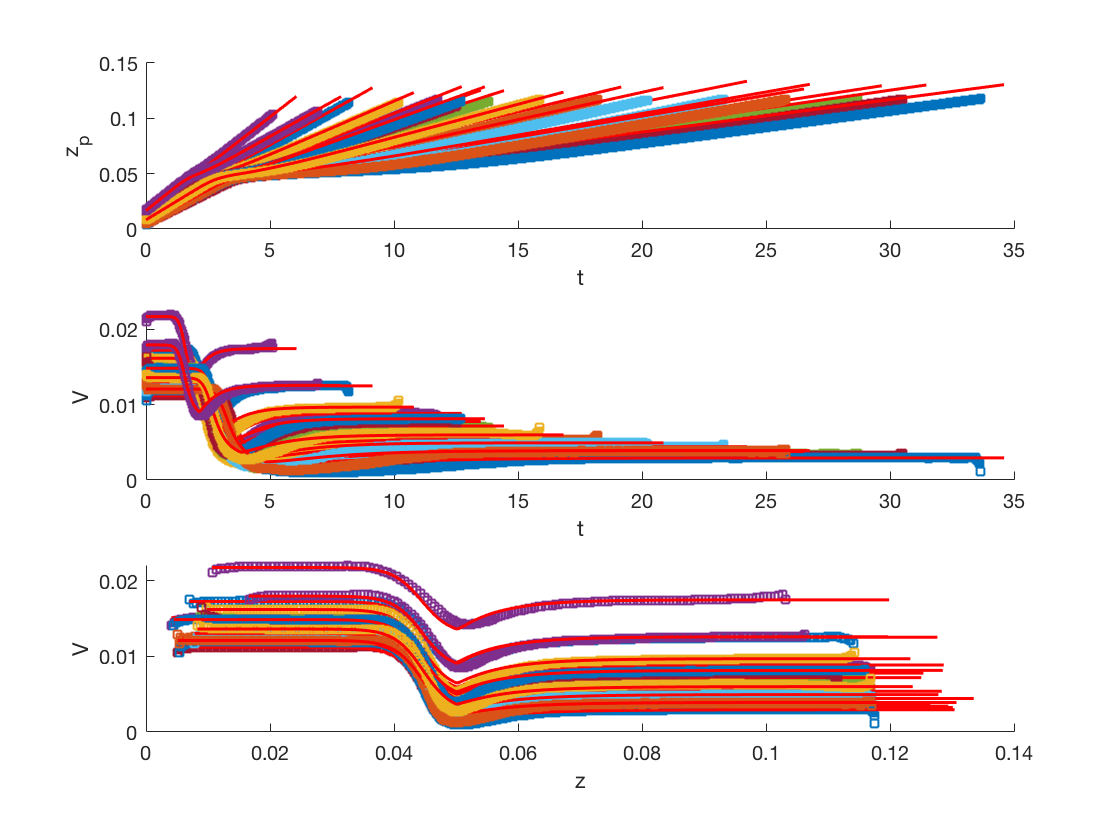

trajP1


trajP2


trajP3


trajP4


trajP5


trajP6


trajP7


trajP8


trajP9


trajP10


trajP11


trajP12


trajP13


trajP14


trajP15


trajP16


trajP17


trajP18


%Select the particle family (flag=1 =>P1,flag=2 =>P2, flag=3 =>P3,flag=4 =>P4, flag=5 => Fernando's particles) 
flag=1;

% Falling particles
if flag ==1;load('Data/TrajP1_complete.mat'); TRAJP =  eval(['TrajP',num2str(flag)]);
end  
if flag ==2;load('Data/TrajP2_complete.mat'); TRAJP =  eval(['TrajP',num2str(flag)]);
end 
if flag ==3;load('Data/TrajP3_complete.mat'); TRAJP =  eval(['TrajP',num2str(flag)]);
end 


% Rising particles
if flag ==4;load('Data/TrajP4_complete.mat'); TRAJP =  eval(['TrajP',num2str(flag)]);
g=-g;
zu   = -0.003;       % upper limit of the interface (entrance) [m]
zl   = 0.0087;       % bottom limit of the interface (exit) [m]
rho2 = 976;          % density top layer [kg/m3]
rho1 = 1025;         % density bottom layer [kg/m3]
nu2  = 1.43e-6;      % viscosity top layer [m2/s]
nu1  = 1.012e-6;     % viscosity bottom layer [m2/s]
end

% Fernando's particles
if flag ==5;load('Data/TrajPF_complete.mat'); 
zu   = 0.125;         % upper limit of the interface (entrance) [m]
zl   = 0.138;          % bottom limit of the interface (exit) [m]
rho1 = 1015;          % density top layer [kg/m3]
rho2 = 1045;          % density bottom layer [kg/m3]
nu1  = 1.17e-06;      % viscosity top layer [m2/s]
nu2  = 1.19e-06;      % viscosity bottom layer [m2/s]
TRAJP =  eval('TrajPF'); lam=0.25;
end


Ind_vec=1:length(TRAJP);


figure
for i=1:length(Ind_vec)
    
    name_to_disp=['trajP',num2str(i)];
    disp(name_to_disp)
    
    rhop=TRAJP(i).rhop;
    d=TRAJP(i).d;
    z_exp  = TRAJP(i).z;
    vz_exp = TRAJP(i).vz;
    t_exp  = TRAJP(i).time;
    t0= t_exp(1);                     % initial time         [s]
    z0= z_exp(1);                     % initial position     [m]
    tend= t_exp(end);                 % final time           [s]
    
    
    
    % calculate the trajectory and plot the results
    
    [t, zp, V] = f_particle(z0, tend, rhop, d, g, zu, zl, rho1, rho2, nu1, nu2,lam);
    
    
    subplot(311)
    hold on
    plot(t_exp-t0,z_exp,'s','markersize',5)
    plot(t,zp,'r','linewidth',1.5)
    xlabel('t'), ylabel('z_p')
    
    subplot(312)
    hold on
    plot(t_exp-t0,vz_exp,'s','markersize',5)
    plot(t,V,'r','linewidth',1.5)
    xlabel('t'), ylabel('V')
    
    subplot(313)
    hold on
    plot(z_exp,vz_exp,'s','markersize',5)
    plot(zp,V,'r','linewidth',1.5)
    xlabel('z'), ylabel('V')
    
end

## function f_particle

type f_particle


% f_particle calculates the trajectory of an inertial particle traversing
% through a stratified fluid layer. The z-axis is defined downwards, and
% layer 1 (the top layer) is for z<zu and layer 2 (the bottom layer) is for
% z>zl. 
%
% SYNTAX [t, zp, V] = f_particle(z0, tend, rhop, d, g, zu, zl, rho1, rho2, nu1, nu2)
%
% INPUT ARGUMENTS
% ---------------
%        z0 : initial particle position [m]
%      tend : simulation time [s]
%      rhop : particle density [kg/m3]
%         d : particle diameter [m]
%         g : gravitational acceleration [m/s2]
%        zu : start of density interface [m]
%        zl : end of density interface [m]
%      rho1 : density of top layer [kg/m3]
%      rho2 : density of bottom layer [kg/m3]
%       nu1 : kinematic viscosity of top layer [m2/s]
%       nu2 : kinematic viscosity of bottom layer [m2/s]
%
% OUTPUT ARGUMENTS
% ----------------
%         t : time interval [s]
%        zp : particle position [m]
%         V : particle velocity [m/s]

functi

## function settlingvelocity

type settlingvelocity


function ws = settlingvelocity(rhop,rhof,g,d,nu)

Cd = @(Re)  0.25 + (24./Re) + (6./(1+Re.^(0.5)));  % drag law

Ap=(pi*d^2)/4;              % surface of the sphere - m2
Vp=(pi*d^3)/6;              % volume  of the sphere - m3

ws = fzero( @(wp) (rhop-rhof) * Vp * g ...
                   - 0.5 * Cd(wp*d/nu)* rhof * Ap * abs(wp) * wp, ...
           [1e-6 1]);
